## 1. Image Loading

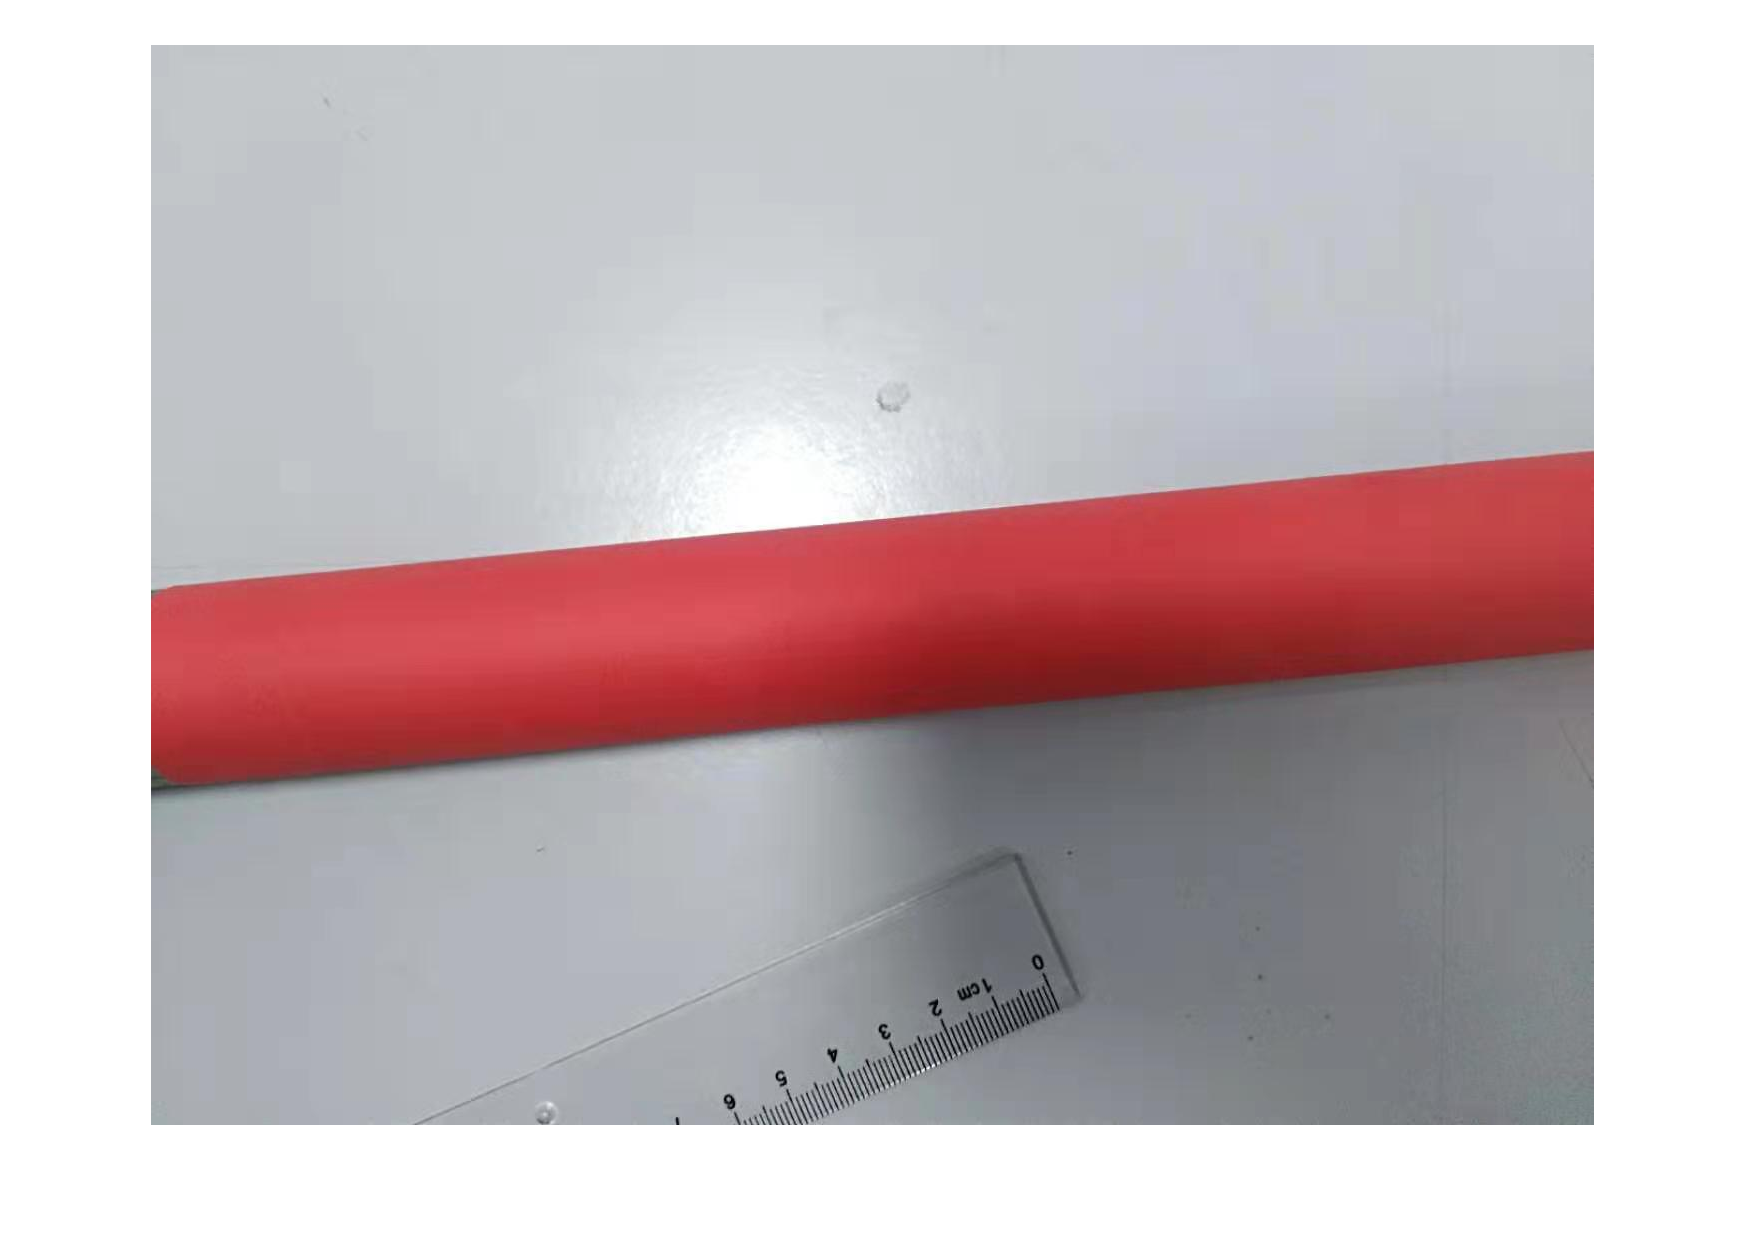

img = imread("./data/3.jpg");
img = im2double(img);
width=size(img,2);
height=size(img,1);
length = sqrt(width*height);

figure, imshow(img);

## 2. Hough Transform

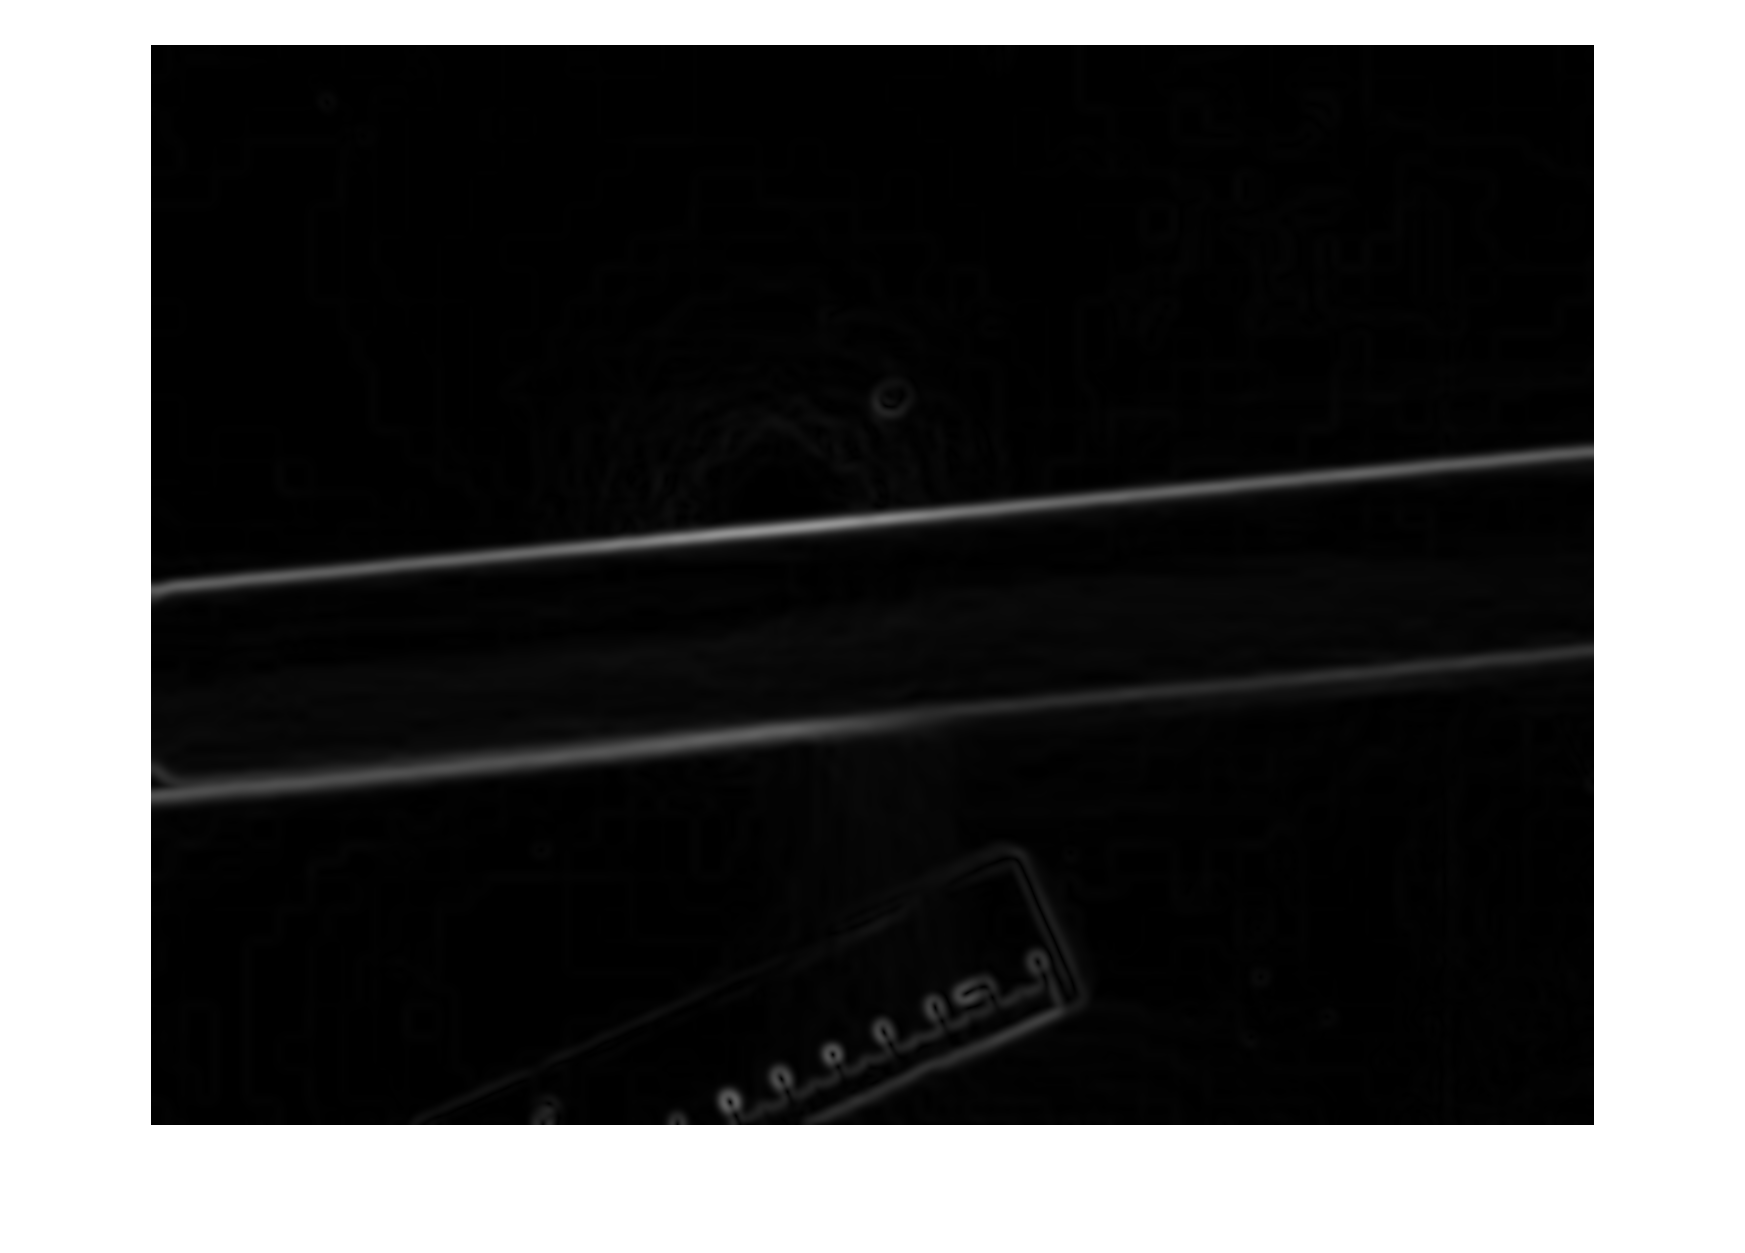

edges = compute_edges(img,5);

figure, imshow(edges);

shrink_scale = 16

shrink_scale = 16

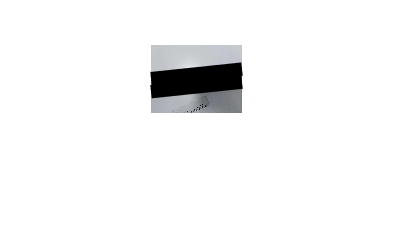

edges_shrinked = edges(1:shrink_scale:end,1:shrink_scale:end);
[theta1, rho1_shrinked, theta2, rho2_shrinked] = find_parallel(edges_shrinked,0.03);

img_shrinked = img(1:shrink_scale:end,1:shrink_scale:end,:);
figure; imshow(img_shrinked), hold on
plot_line(width,height,theta1,rho1_shrinked);
plot_line(width,height,theta2,rho2_shrinked);


rho1 = rho1_shrinked * shrink_scale;
rho2 = rho2_shrinked * shrink_scale;

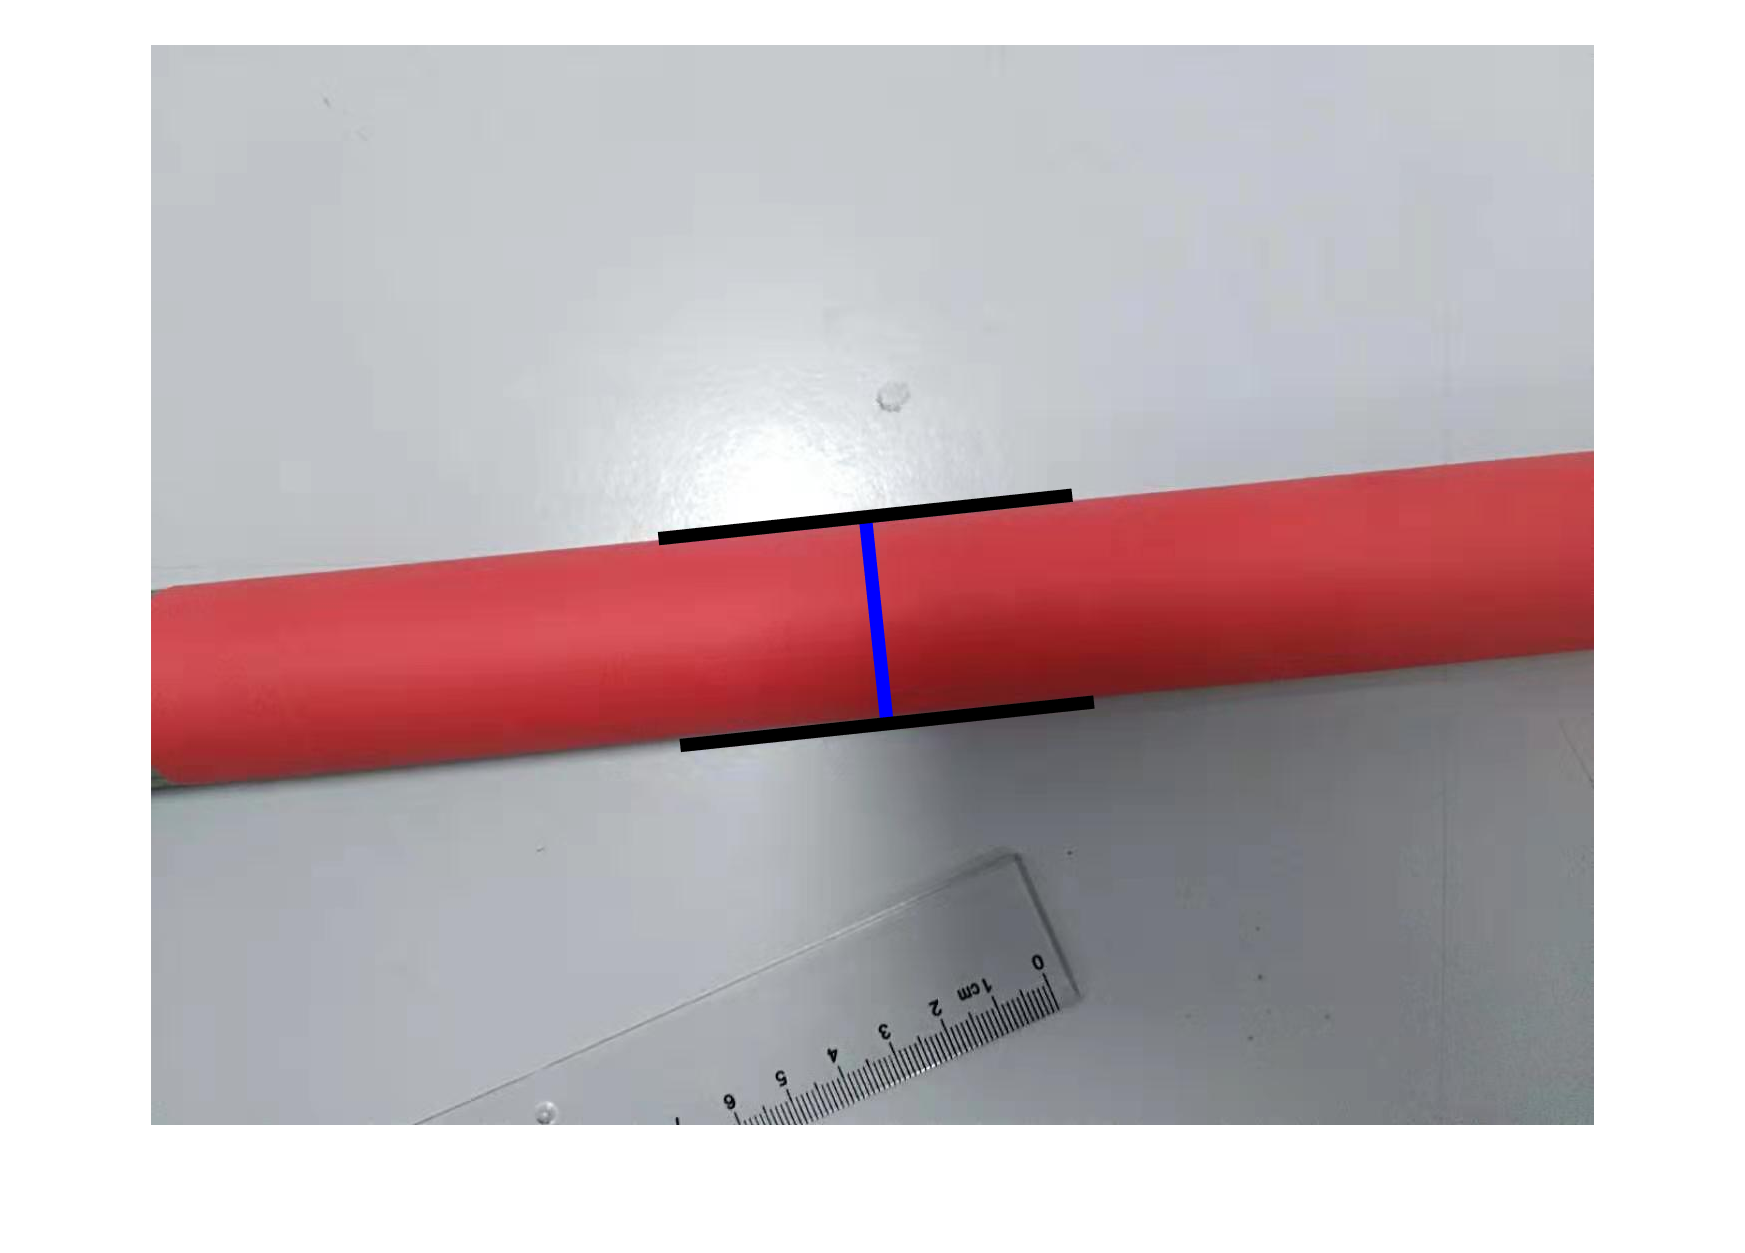

[p1, p2] = initial_points(theta1,rho1,theta2,rho2,width,height);

figure, imshow(img), hold on
plot_ruler(p1,p2);

## 3. Gradient Decent

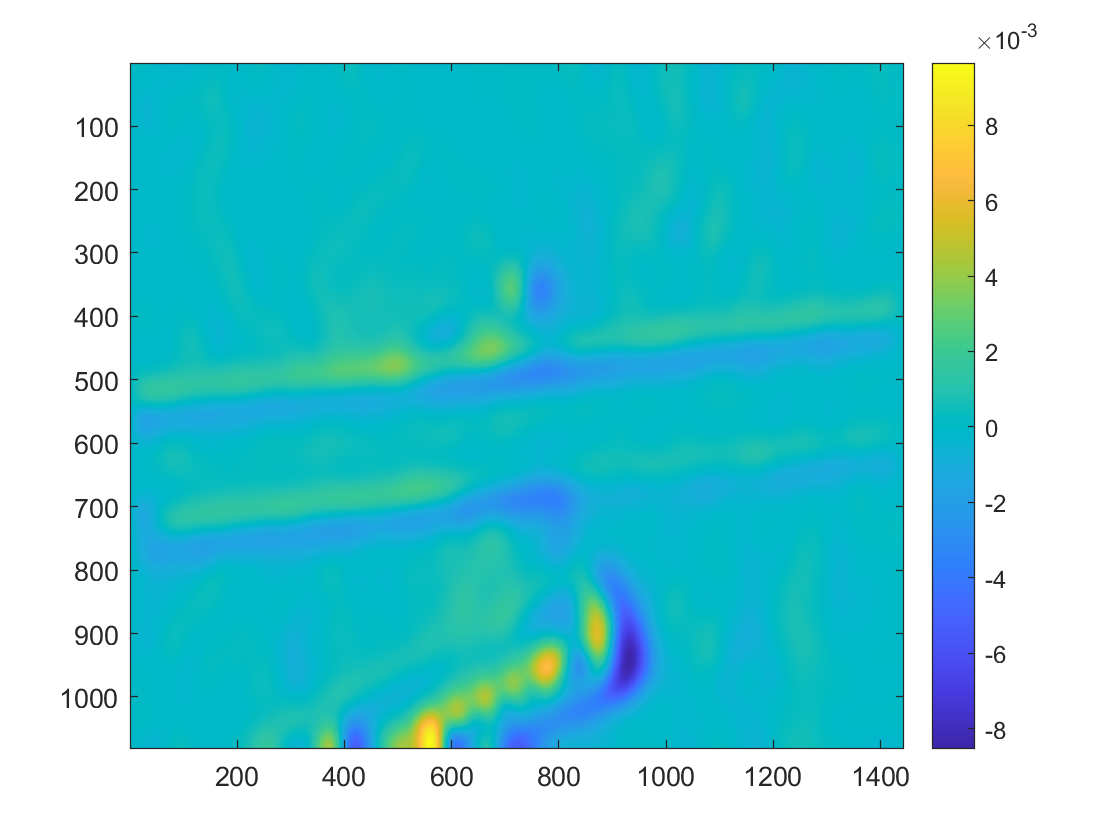

grad = compute_grad(edges,25);

figure, imagesc(grad(:,:,1)), colorbar;

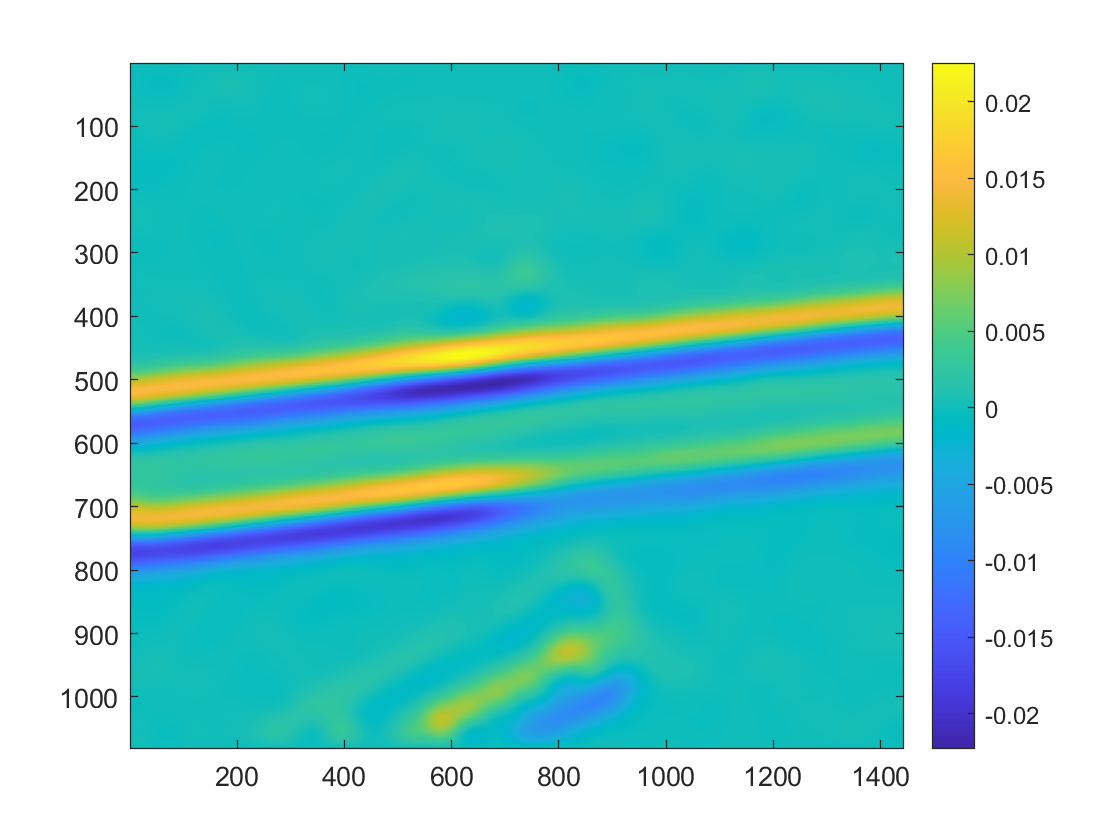

figure, imagesc(grad(:,:,2)), colorbar;

% 扰动
%p1 = p1 + randn(size(p1))*(length/100);
%p2 = p2 + randn(size(p2))*(length/100);

figure, imshow(img), hold on
plot_ruler(p1,p2);

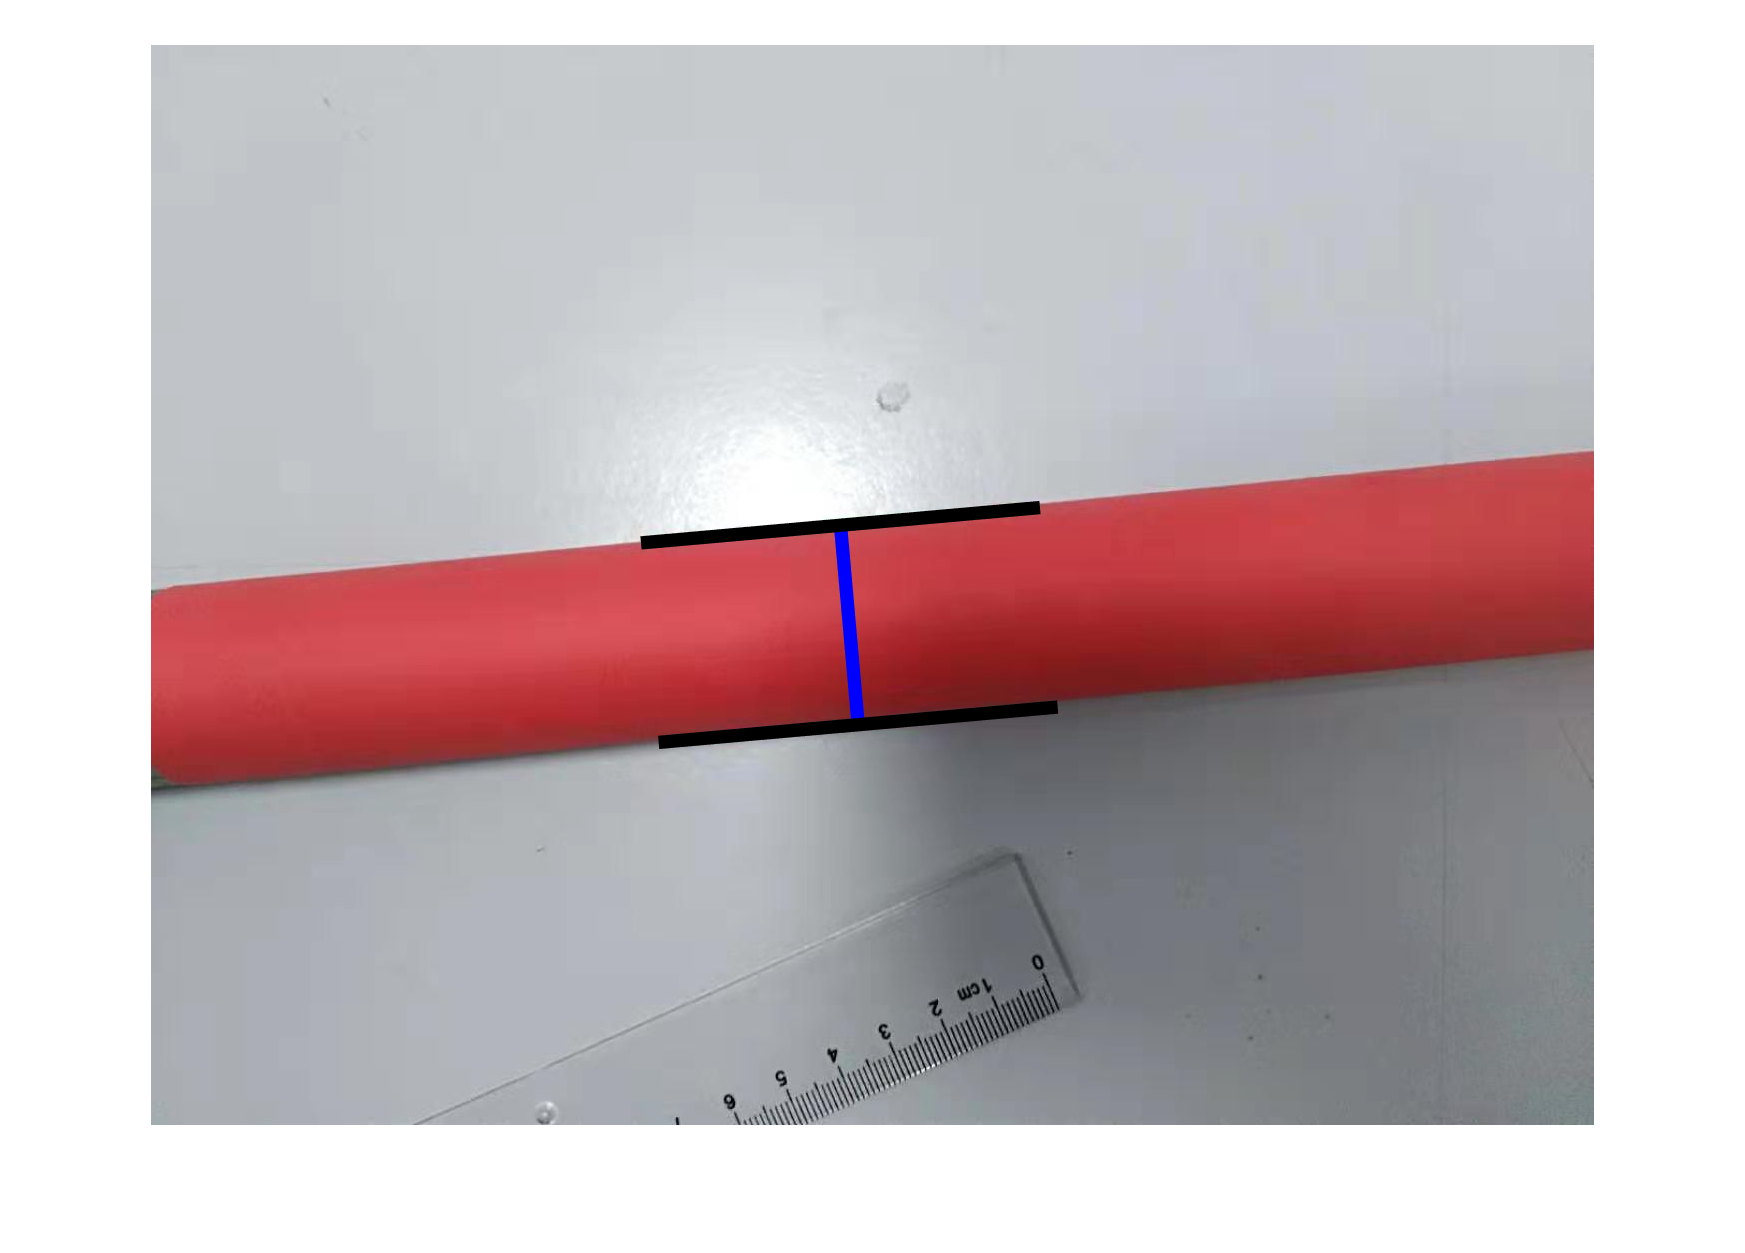

v1 = 0.0;
v2 = 0.0;
[p1,p2,v1,v2,steps,D,dD] = gradient_decent(grad,p1,p2,v1,v2);

figure, imshow(img), hold on
plot_ruler(p1,p2);


steps

steps = 9

result = D

result = 200.2516

uncertainty = dD

uncertainty = 0.1827